# Numerical Optimization HW 03

objective_function_1(x,y) = (x+2y-6)^2 + (2x+y-6)^2

objective_function_2(x,y) = 50(y-x)^2 + (1-x)^2

objective_function_3(x,y)=(1.5-x+xy)^2 + (2.25-x+xy^2)^2 + (2.625-x+xy^3)^2

# Objective function 1

objective_function_1(x,y) = (x+2y-6)^2 + (2x+y-6)^2

## initialization

% Create random inputs X and Y
% N=3 : triangle
[x, y] = create_random_N(3,7)

x =      6    -7    -6


y =      2     4     7


% define function and input
objective_function = @objective_function_1;
function_value = objective_function(x, y);

## Nelder-Mead method

alpha = 3;
beta = 1.5;
gamma = 0.3;
termination_condition = 0.000001;
[output_x, output_y, dummy, dummy] = Nelder_and_Mead_method(x, y, objective_function, alpha, beta, gamma, termination_condition);

the termination condition: 0.000100
the number of iteration: 15
Elapsed time is 0.009514 seconds.


disp(output_x)

    3.0527    3.0523    3.0524



disp(output_y)

    1.3228    0.7225    0.4639



the termination condition: 0.000001

the number of iteration: 28

Elapsed time is 0.002305 seconds.

    1.2449    1.2449    1.2449

    2.4095    2.8507    3.0489

## contour plot animation (**warning!** execute on the terminal or Output inline mode)

the termination condition: 0.100000
the number of iteration: 14
Elapsed time is 0.005391 seconds.


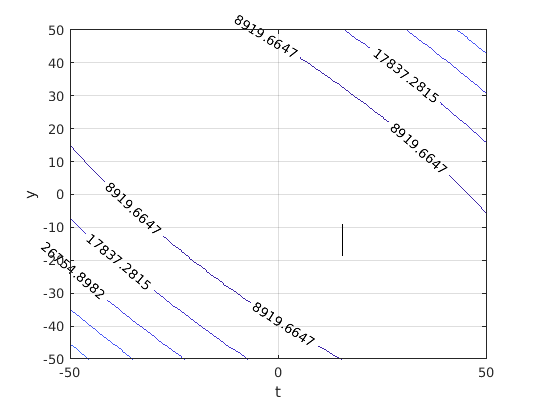

% for contour plot
range = 100;
x_grid = linspace(-range,range);
y_grid = linspace(-range,range);
[X, Y] = meshgrid(x_grid,y_grid);
Z = objective_function(X,Y);

% for polygon
[x, y] = create_random_N(3,50);
[dummy, dummy, x_iteration, y_iteration] = Nelder_and_Mead_method(x, y, objective_function, alpha, beta, gamma, termination_condition);
for k = 1:length(x_iteration)/3
    % contour plot
    contour(X,Y,Z,20, 'ShowText','on')
    hold on
    
    % marker plot
    %plot(t(1:k), y(1:k))
    %hold on

    polygon = polyshape([x_iteration(3*k-2) x_iteration(3*k-1) x_iteration(3*k)],[y_iteration(3*k-2) y_iteration(3*k-1) y_iteration(3*k)]);
    plot(polygon)
    
    % graph properties
    axis([-50 50 -50 50])
    grid on
    xlabel('t')
    ylabel('y')
    %legend('cos(t) marker', 'cos(t)')
    pause(0.1)
    
    if k ~= length(x_iteration)/3
        clf
    end
end

## Powell's method

termination_condition = 0.1;
[output_x, output_y, dummy, dummy] = Powells_method(x, y, objective_function, termination_condition);

the termination condition: 0.100000
the number of iteration: 14
Elapsed time is 0.062494 seconds.


disp(output_x)

    2.0001



disp(output_y)

    1.9999



the termination condition: 0.100000

the number of iteration: 3

Elapsed time is 0.006084 seconds.

    2.0001

    1.9999

## contour plot animation

% for contour plot
range = 100;
x_grid = linspace(-range,range);
y_grid = linspace(-range,range);
[X, Y] = meshgrid(x_grid,y_grid);
Z = objective_function(X,Y);

% for polygon
[x, y] = create_random_N(3,50);
[dummy, dummy, x_iteration, y_iteration] = Powells_method(x, y, objective_function,termination_condition);

for k = 1:length(x_iteration)
    % contour plot
    contour(X,Y,Z,20, 'ShowText','on')
    hold on
    
    % marker plot
    %plot(t(1:k), y(1:k))
    %hold on

    plot(x_iteration(k), y_iteration(k), 'x')
    
    % graph properties
    axis([-50 50 -50 50])
    grid on
    xlabel('t')
    ylabel('y')
    %legend('cos(t) marker', 'cos(t)')
    pause(1.1)
    
    if k ~= length(x_iteration)
        clf
    end
end

## Validation

3D plot

grid_x = -50:50;
grid_y = -50:50;
[X,Y] = meshgrid(grid_x,grid_y);
Z = objective_function(X,Y);
surf(X,Y,Z)
clear grid_x grid_y X Y Z

Contour plot

range = 100;
x = linspace(-range,range);
y = linspace(-range,range);
[X, Y] = meshgrid(x,y);
Z = objective_function(X,Y);
contour(X,Y,Z,20, 'ShowText','on')

By optimality condition, the gradient in mininum point should be (0,0). Thus, the minimum point is (2,2). Both of the methods works correctly.

# Objective function 2

objective_function_2(x,y) = 50(y-x)^2 + (1-x)^2

## initialization

% Create random inputs X and Y
% N=3 : triangle
[x, y] = create_random_N(3,30)

% define function and input
objective_function = @objective_function_2;
function_value = objective_function(x, y);

## Nelder-Mead method

alpha = 3;
beta = 1.5;
gamma = 0.3;
termination_condition = 0.000001;
[output_x, output_y, dummy, dummy] = Nelder_and_Mead_method(x, y, objective_function, alpha, beta, gamma, termination_condition);
disp(output_x)
disp(output_y)

the termination condition: 0.000001

the number of iteration: 42

Elapsed time is 0.012476 seconds.

    1.0052    1.0085    1.0066

    1.0047    1.0080    1.0057

## contour plot animation (**warning!** execute on the terminal)

% for contour plot
range = 100;
x_grid = linspace(-range,range);
y_grid = linspace(-range,range);
[X, Y] = meshgrid(x_grid,y_grid);
Z = objective_function(X,Y);

% for polygon
[x, y] = create_random_N(3,50);
[dummy, dummy, x_iteration, y_iteration] = Nelder_and_Mead_method(x, y, objective_function, alpha, beta, gamma, termination_condition);

for k = 1:length(x_iteration)/3
    % contour plot
    contour(X,Y,Z,20, 'ShowText','on')
    hold on
    
    % marker plot
    %plot(t(1:k), y(1:k))
    %hold on

    polygon = polyshape([x_iteration(3*k-2) x_iteration(3*k-1) x_iteration(3*k)],[y_iteration(3*k-2) y_iteration(3*k-1) y_iteration(3*k)]);
    plot(polygon)
    
    % graph properties
    axis([-20 20 -20 20])
    grid on
    xlabel('t')
    ylabel('y')
    %legend('cos(t) marker', 'cos(t)')
    pause(0.1)
    
    if k ~= length(x_iteration)/3
        clf
    end
end

## Powell's method

termination_condition = 0.1;
[output_x, output_y, dummy, dummy] = Powells_method(x, y, objective_function, termination_condition);
disp(output_x)
disp(output_y)

the termination condition: 0.100000

the number of iteration: 5

Elapsed time is 0.008305 seconds.

    1.0000

    1.0000

## contour plot animation

% for contour plot
range = 100;
x_grid = linspace(-range,range);
y_grid = linspace(-range,range);
[X, Y] = meshgrid(x_grid,y_grid);
Z = objective_function(X,Y);

% for polygon
[x, y] = create_random_N(3,50);
[dummy, dummy, x_iteration, y_iteration] = Powells_method(x, y, objective_function,termination_condition);

for k = 1:length(x_iteration)
    % contour plot
    contour(X,Y,Z,20, 'ShowText','on')
    hold on
    
    % marker plot
    %plot(t(1:k), y(1:k))
    %hold on

    plot(x_iteration(k), y_iteration(k), 'x')
    
    % graph properties
    axis([-20 20 -20 20])
    grid on
    xlabel('t')
    ylabel('y')
    %legend('cos(t) marker', 'cos(t)')
    pause(1.1)
    
    if k ~= length(x_iteration)
        clf
    end
end

## Validation

3D plot

grid_x = -20:20;
grid_y = -20:20;
[X,Y] = meshgrid(grid_x,grid_y);
Z = objective_function(X,Y);
surf(X,Y,Z)
clear grid_x grid_y X Y Z

Contour plot

range = 20;
x = linspace(-range,range);
y = linspace(-range,range);
[X, Y] = meshgrid(x,y);
Z = objective_function(X,Y);
contour(X,Y,Z,20, 'ShowText','on')

By optimality condition, the gradient in mininum point should be (0,0). Thus, the minimum point is (1,1). Both of the methods works correctly.

# Objective function 3

objective_function_3(x,y)=(1.5-x+xy)^2 + (2.25-x+xy^2)^2 + (2.625-x+xy^3)^2

## initialization

% Create random inputs X and Y
% N=3 : triangle
[x, y] = create_random_N(3,4)

x =     -5     3    -4


y =     -8     1    -7


% define function and input
objective_function = @objective_function_3;
function_value = objective_function(x, y);

## Nelder-Mead method

alpha = 3;
beta = 1.5;
gamma = 0.3;
termination_condition = 0.0001;
[output_x, output_y, dummy, dummy] = Nelder_and_Mead_method(x, y, objective_function, alpha, beta, gamma, termination_condition);

the termination condition: 0.000001
the number of iteration: 51
Elapsed time is 0.006288 seconds.


disp(output_x)

    3.0000    3.0000    3.0000



disp(output_y)

    1.0000   -2.0001   -2.0001



the termination condition: 0.000001

the number of iteration: 30

Elapsed time is 0.004294 seconds.

    1.9711    1.9711    1.9711

    0.0127   -0.9866   -1.0625

## contour plot animation (**warning!** execute on the terminal)

% for contour plot
range = 20;
x_grid = linspace(-range,range);
y_grid = linspace(-range,range);
[X, Y] = meshgrid(x_grid,y_grid);
Z = objective_function(X,Y);

% for polygon
[x, y] = create_random_N(3,50);
[dummy, dummy, x_iteration, y_iteration] = Nelder_and_Mead_method(x, y, objective_function, alpha, beta, gamma, termination_condition);

the termination condition: 0.000001
the number of iteration: 43
Elapsed time is 0.004355 seconds.



for k = 1:length(x_iteration)/3
    % contour plot
    contour(X,Y,Z,20, 'ShowText','on')
    hold on
    
    % marker plot
    %plot(t(1:k), y(1:k))
    %hold on

    polygon = polyshape([x_iteration(3*k-2) x_iteration(3*k-1) x_iteration(3*k)],[y_iteration(3*k-2) y_iteration(3*k-1) y_iteration(3*k)]);
    plot(polygon)
    
    % graph properties
    axis([-20 20 -20 20])
    grid on
    xlabel('t')
    ylabel('y')
    %legend('cos(t) marker', 'cos(t)')
    pause(0.1)
    
    if k ~= length(x_iteration)/3
        clf
    end
end

## Powell's method

termination_condition = 0.001;
[output_x, output_y, dummy, dummy] = Powells_method(x, y, objective_function, termination_condition);

the termination condition: 0.100000
the number of iteration: 286
Elapsed time is 0.322841 seconds.


disp(output_x)

  -7.6152e+04



disp(output_y)

    1.0000



the termination condition: 0.100000

the number of iteration: 274

Elapsed time is 0.230726 seconds.

  -6.5856e+04

    1.0000

## contour plot animation

% for contour plot
range = 20;
x_grid = linspace(-range,range);
y_grid = linspace(-range,range);
[X, Y] = meshgrid(x_grid,y_grid);
Z = objective_function(X,Y);

% for polygon
[x, y] = create_random_N(3,50);
[dummy, dummy, x_iteration, y_iteration] = Powells_method(x, y, objective_function,termination_condition);

the termination condition: 0.100000
the number of iteration: 293
Elapsed time is 0.299915 seconds.


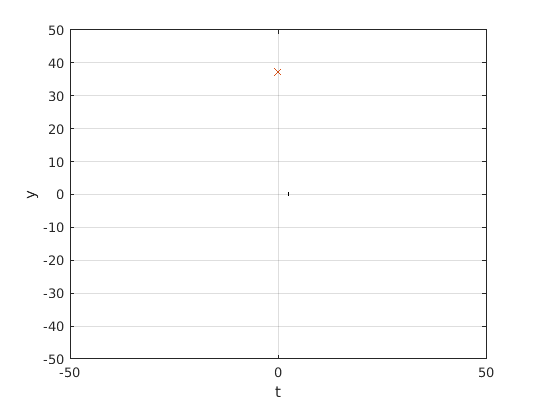

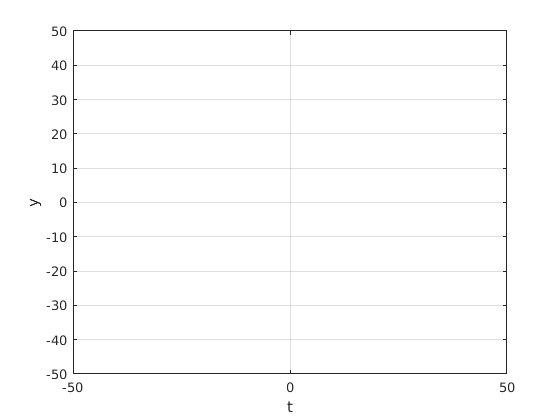

for k = 1:length(x_iteration)
    % contour plot
    contour(X,Y,Z,20, 'ShowText','on')
    hold on
    
    % marker plot
    %plot(t(1:k), y(1:k))
    %hold on

    plot(x_iteration(k), y_iteration(k), 'x')
    
    % graph properties
    axis([-20 20 -20 20])
    grid on
    xlabel('t')
    ylabel('y')
    %legend('cos(t) marker', 'cos(t)')
    pause(1.1)
    
    if k ~= length(x_iteration)
        clf
    end
end% for contour plot

## Validation

3D plot

grid_x = -20:20;
grid_y = -20:20;
[X,Y] = meshgrid(grid_x,grid_y);
Z = objective_function(X,Y);
surf(X,Y,Z)
clear grid_x grid_y X Y Z

Contour plot

range = 100;
x = linspace(-range,range);
y = linspace(-range,range);
[X, Y] = meshgrid(x,y);
Z = objective_function(X,Y);
contour(X,Y,Z,30, 'ShowText','on')

It has multiple stationary point. Its saddle point are (0,1) and (0.1, -2.644), and its minimum point is (3,0.5)

# Conclusion

- Generally, Powell's method has the higher accuracy than Nelder and Mead method. Powell's method requires a few iterations than Nelder and Mead method. 

- Nelder amd Mead method get the larger impact on initial parameter than Powell's method. In otherword, Powell's method is robust.

- Both method shows good performance in simple function such as function 1 and function 2. (They cast a output near global minimum frequently.) However, Both method casts local optimum on function 3.

- In short, Powell's method shows better performance than Nelder and Mead method in view point of accuracy, convergence speed (iteration), and robustness.